clear all

h = logspace(-20,0,100);
x0 = pi/4;
derivative= dydx(x0);

der = 0.7071


dydx_central_approx = (sin(x0 + h) - sin(x0 - h)) ./ (2*h)                            

dydx_central_approx =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.8054    0.5058    0.9530    0.7980    0.6264    0.7082    0.6918    0.7138    0.7212    0.7222    0.7073    0.7097    0.7065    0.7084    0.7068    0.7075    0.7071    0.7071    0.7070    0.7070    0.7072    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071


abserr_cen = abs(derivative - dydx_central_approx);

truncation_error_cen = cos(x0).*h.^2/ (factorial(3))

truncation_error_cen =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


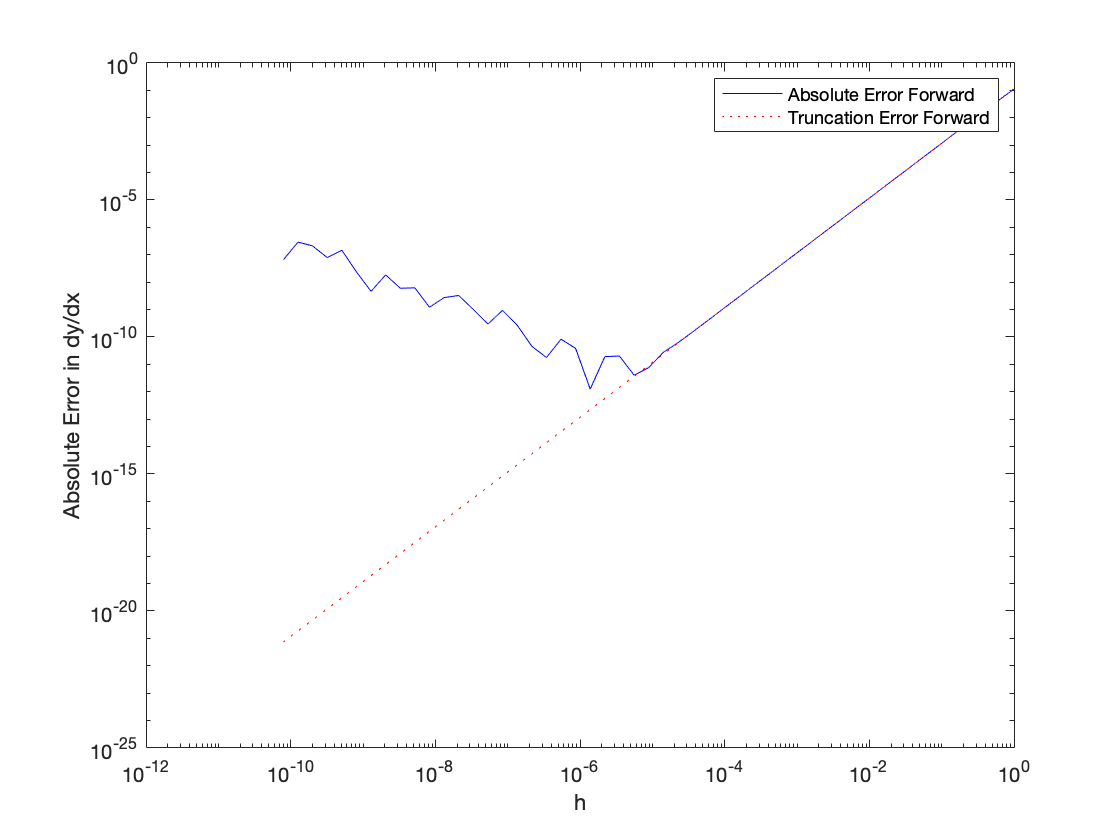


clf
figure(1)
loglog(h(50:100),abserr_cen(50:100),'b')
hold on
figure(1)
loglog(h(50:100),truncation_error_cen(50:100),'r:')

xlabel('h')
ylabel('Absolute Error in dy/dx')

legend('Absolute Error Forward','Truncation Error Forward')

function der = dydx(x)
    der = cos(x)
end